a=1+mod(494,3);

Problem1

SubProblem1

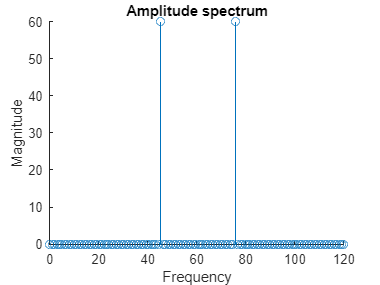

Fs = 120;
a=1+mod(494,3);
t = 0:1/Fs:2;
y = sin(2*pi*15*a*t);
Y = fft(y,120);
N = length(Y);
f = (0:Fs/(N-1):Fs);
figure
hold on
stem(f(1:120),abs(Y))
title("Amplitude spectrum");
xlabel("Frequency");
ylabel("Magnitude");

Problem1 

Subproblem 2

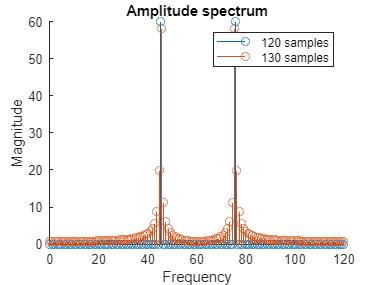

n = 130;
Y1 = fft(y,n);
N = length(Y1);
f = (0:Fs/(N-1):Fs);
stem(f(1:n),abs(Y1))
legend("120 samples","130 samples");
hold off

Problem 1

Subproblem 3

%for i = 40:40:240 
    %Yn = fft(y,i);
    %N = length(Yn);
    %f = (0:Fs/(N-1):Fs);
    %hold on
    %stem(f,abs(Yn))
    %title("Amplitude spectrum")
    %hold off
%end
%legend("40 samples","80 samples","120 samples","160 samples","200 samples","240 samples","130 samples")
n = 128

n = 128

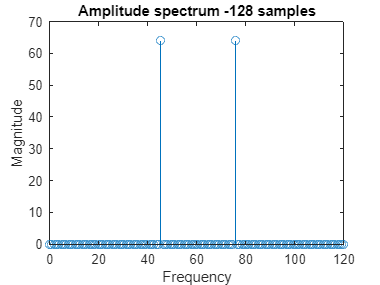

Y2 = fft(y,n);
N = length(Y2);
f = (0:Fs/(N-1):Fs);
stem(f(1:n),abs(Y2))
title("Amplitude spectrum -128 samples");
xlabel("Frequency");
ylabel("Magnitude");

Problem 2

Fs = 200

Fs = 200

t = 0:1/Fs:10

t =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


A = 160

A = 160

B = 166

B = 166

xa = 0.1*sin(A*pi*t) + cos(B*pi*t);
f = (0:Fs/(length(xa)-1):Fs)*10

f = 1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


n = [215 415 1115 1515 1915]

n =          215         415        1115        1515        1915


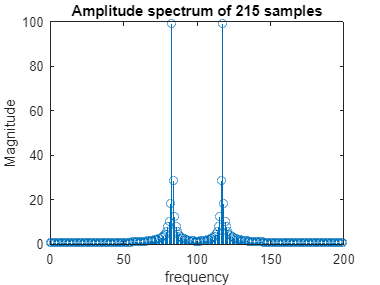

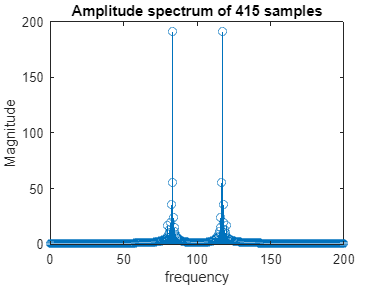

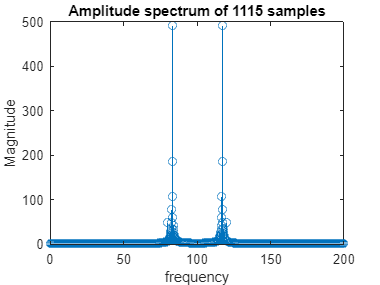

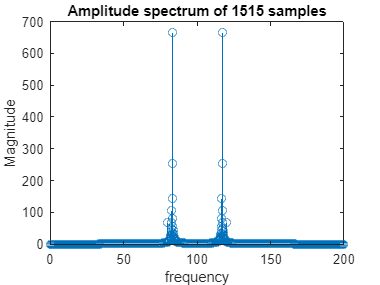

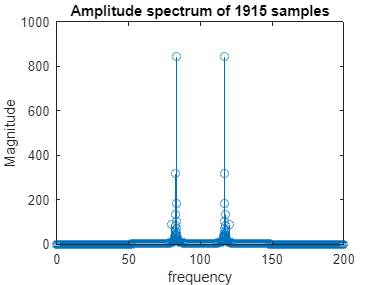

for i = n
    figure
    Z = fft(xa,i);
    stem(200*f(1:i)/i,abs(Z))
    title("Amplitude spectrum of " + i + " samples")
    xlabel("frequency")
    ylabel("Magnitude")
end

Problem 3

Fs = 200

Fs = 200

t = 0:1/Fs:10

t =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


A = 160

A = 160

B = 166

B = 166

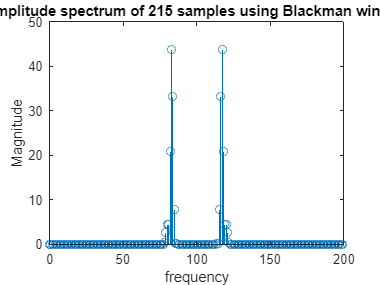

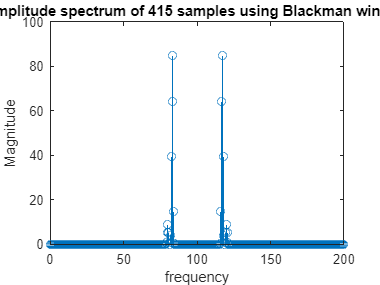

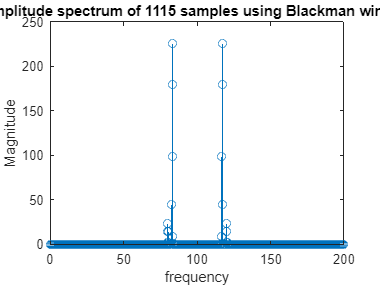

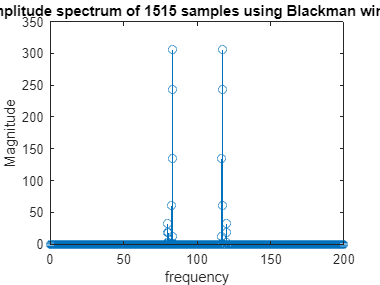

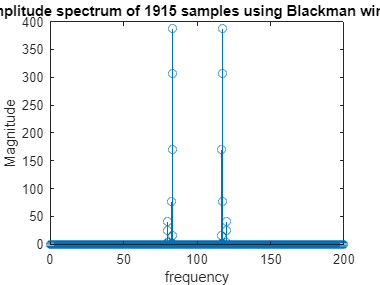

xa = 0.1*sin(A*pi*t) + cos(B*pi*t);
f = (0:Fs/(length(xa)-1):Fs)*10;
n = [215 415 1115 1515 1915];
for i = n
    figure
    window = blackman(i);
    windowed_signal = xa(1:i) .* (window)';
    Z = fft(windowed_signal,i);
    stem(200*f(1:i)/i,abs(Z))
    title("Amplitude spectrum of " + i + " samples using Blackman window")
    xlabel("frequency")
    ylabel("Magnitude")
end

Problem4

load Exp4Data2.txt
z = Exp4Data2

z =     0.1000    0.9829   -0.2608   -0.9292    0.4099    0.8522   -0.5437   -0.7550    0.6594    0.6411   -0.7549   -0.5144    0.8289    0.3784   -0.8807   -0.2367    0.9102    0.0929   -0.9177    0.0500    0.9039   -0.1891   -0.8700    0.3219    0.8171   -0.4461   -0.7467    0.5595    0.6603   -0.6603   -0.5595    0.7467    0.4461   -0.8171   -0.3219    0.8700    0.1891   -0.9039   -0.0500    0.9177   -0.0929   -0.9102    0.2367    0.8807   -0.3784   -0.8289    0.5144    0.7549   -0.6411   -0.6594


Z = fft(z);
Fs = 1

Fs = 1

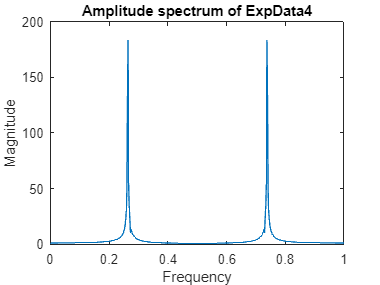

f= 0:Fs/(length(z)-1):Fs;
plot(f,abs(Z))
title("Amplitude spectrum of ExpData4")
xlabel("Frequency")
ylabel("Magnitude")

[maxm,value] = max(abs(Z));
fund_freq = f(value)

fund_freq = 0.2645

factor = [f(value) ; Fs - f(value)]/Fs

factor =     0.2645
    0.7355


Problem4

SubProblem 1

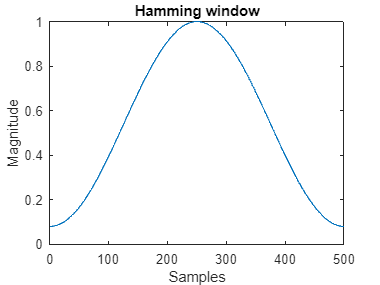

h = hamming(500);
plot(h)
title("Hamming window")
xlabel("Samples")
ylabel("Magnitude")


z1 = z.*(h)';
Z = fft(z1,10000);
Fs = 1

Fs = 1

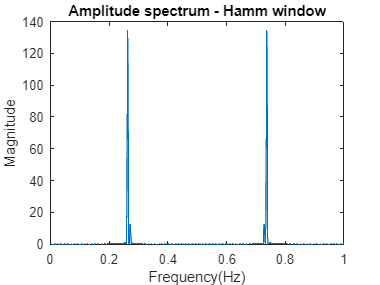

f= 0:Fs/(length(Z)-1):Fs;
plot(f,abs(Z))
title("Amplitude spectrum - Hamm window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

%[value,idx] = max(abs(Z));
%fund_freq = f(idx)
%factor = [f(idx) ; Fs - f(idx)]/Fs

Problem4

SubProblem 2

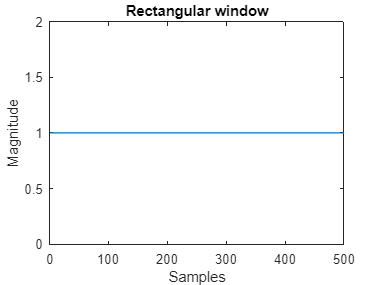

h = rectwin(500);
plot(h)
title("Rectangular window")
xlabel("Samples")
ylabel("Magnitude")

z1 = z.*(h)';
Z = fft(z1,10000);
Fs = 1

Fs = 1

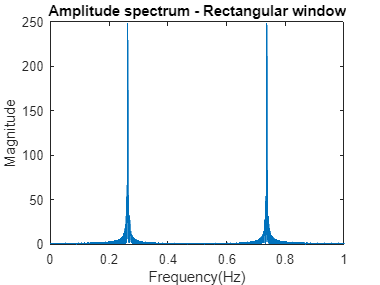

f= 0:Fs/(length(Z)-1):Fs;
plot(f,abs(Z))
title("Amplitude spectrum - Rectangular window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

%[value,idx] = max(abs(Z));
%fund_freq = f(idx)
%factor = [f(idx) ; Fs - f(idx)]/Fs